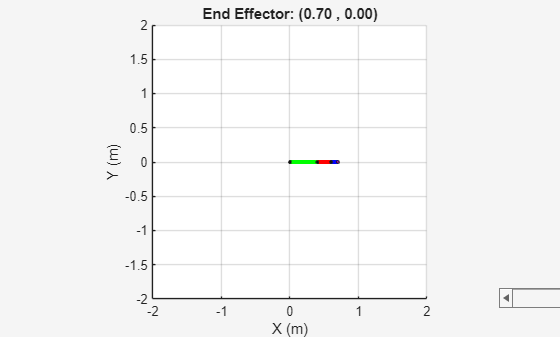

clc; clear; close all;

% --- Figure setup ---
f1 = figure('Name','3-Link Planar Manipulator with Sliders','NumberTitle','off');
axis equal; grid on;
xlim([-2 2]); ylim([-2 2]);
xlabel('X (m)'); ylabel('Y (m)');
title('Interactive 3-Link Planar Manipulator');
hold on;

% --- Circle parameters (for joints) ---
r = 0.02; 
N = 200; 
t = linspace(0,2*pi,N);

% --- Link lengths ---
L1 = 0.4; L2 = 0.2; L3 = 0.1;

% --- Initial plots (horizontal orientation) ---
Link1 = plot([0 L1],[0 0],'g-','LineWidth',3);
Link2 = plot([L1 L1+L2],[0 0],'r-','LineWidth',3);
Link3 = plot([L1+L2 L1+L2+L3],[0 0],'b-','LineWidth',3);

Joint1 = patch(r*cos(t), r*sin(t), 'k'); % Base joint
Joint2 = patch(L1+r*cos(t), r*sin(t), 'k'); % 2nd joint
Joint3 = patch((L1+L2)+r*cos(t), r*sin(t), 'k'); % 3rd joint
EndEff = patch((L1+L2+L3)+r*cos(t), r*sin(t), 'm'); % End-effector

% --- Sliders ---
xSlider = uicontrol('Style','slider','Min',-1,'Max',1,'Value',L1+L2+L3,...
    'Position',[500 30 150 20],'Callback',@updateArm1);
uicontrol('Style','text','Position',[500 10 150 20],'String','x');

ySlider = uicontrol('Style','slider','Min',-1,'Max',1,'Value',0,...
    'Position',[700 30 150 20],'Callback',@updateArm1);
uicontrol('Style','text','Position',[700 10 150 20],'String','y');

phiSlider = uicontrol('Style','slider','Min',0,'Max',2*pi,'Value',0,...
    'Position',[900 30 150 20],'Callback',@updateArm1);
uicontrol('Style','text','Position',[900 10 150 20],'String','phi (rad)');

% --- Configuration Checkbox ---
config = uicontrol('Style', 'checkbox','String', 'Elbow-Down/Up (checked/unchecked) ', ...
         'Position', [1100 30 150 20], 'Value', 0,'Callback', @updateArm1);

% --- Text for joint positions ---
posText = uicontrol('Style','text','Position',[700 200 250 120],...
    'String','Joint positions will appear here','HorizontalAlignment','left','FontName','FixedWidth');

% --- Store handles in structure ---
data.L1 = L1; data.L2 = L2; data.L3 = L3;
data.r = r; data.t = t;
data.Link1 = Link1; data.Link2 = Link2; data.Link3 = Link3;
data.Joint1 = Joint1; data.Joint2 = Joint2; data.Joint3 = Joint3; data.EndEff = EndEff;
data.xSlider = xSlider; 
data.ySlider = ySlider;
data.phiSlider = phiSlider;
data.config = config;
data.posText = posText;
guidata(f1, data);

% --- Initial update to draw arm ---
updateArm1(f1, []);


% === Update function (called whenever a slider moves) ===
function updateArm1(src,~)
    data = guidata(src);
    % Read slider values
    x = get(data.xSlider,'Value');
    y = get(data.ySlider,'Value');
    phi = get(data.phiSlider,'Value');
    cfg = get(data.config,'Value'); % elbow config

    % --- Call IK function ---
    [q1,q2,q3] = ik_3link(x, y, 0, phi, cfg); % <— your own IK
    
    % --- Call FK function---
    O0 = [0, 0]; % Base origin for forward kinematics
    [O1, O2, O3] = fk_3link([q1, q2, q3]);

    % --- Update link lines ---
    set(data.Link1,'XData',[O0(1) O1(1)],'YData',[O0(2) O1(2)]);
    set(data.Link2,'XData',[O1(1) O2(1)],'YData',[O1(2) O2(2)]);
    set(data.Link3,'XData',[O2(1) O3(1)],'YData',[O2(2) O3(2)]);

    % --- Update joint markers ---
    set(data.Joint1,'XData',O0(1)+data.r*cos(data.t),'YData',O0(2)+data.r*sin(data.t));
    set(data.Joint2,'XData',O1(1)+data.r*cos(data.t),'YData',O1(2)+data.r*sin(data.t));
    set(data.Joint3,'XData',O2(1)+data.r*cos(data.t),'YData',O2(2)+data.r*sin(data.t));
    set(data.EndEff,'XData',O3(1)+data.r*cos(data.t),'YData',O3(2)+data.r*sin(data.t));

     % --- Display positions in side panel ---
    infoStr = sprintf(['Joint Positions:\n' ...
                       'O1: (%.2f , %.2f)\n' ...
                       'O2: (%.2f , %.2f)\n' ...
                       'O3: (%.2f , %.2f)\n'],...
                       O1(1),O1(2), O2(1),O2(2), O3(1),O3(2));
    set(data.posText,'String',infoStr);

    % --- Display current end-effector coordinates ---
    title(sprintf('End Effector: (%.2f , %.2f)', O3(1), O3(2)));

    drawnow;
end
